# Homework 5

**Name:** Jackson Lee

**Due Date: **

clear, clc

## Problem #1 - Comparing Runge-Kutta methods

**SETUP FOR PROBLEM**

dydt = @(x,y) (38*x.^2+32*x+47)./(8*y.^2);
x0 = 1.5;
xf = 5.5;
y0 = 2.9;


**a) Analytically**

syms y(x)
ode = diff(y,x) == (38*x.^2+32*x+47)./(8*y.^2);
cond = y(x0) == y0;
yExact(x) = dsolve(ode, cond)

$$yExact(x) = \frac{{\left(38\,x^{3}+48\,x^{2}+141\,x-\frac{126319}{500}\right)}^{1/3}}{2}$$

**b) Using Euler's method**

h1 = 1;
h2 = .5;
x_vals1 = x0:h1:xf;
x_vals2 = x0:h2:xf;

y_Euler1 = zeros(size(x_vals1));
y_Euler1(1) = y0;
for i = 1:(length(y_Euler1)-1)
    phi = dydt(x_vals1(i), y_Euler1(i));
    y_Euler1(i+1) = y_Euler1(i) + phi*h1;
end

y_Euler2 = zeros(size(x_vals2));
y_Euler2(1) = y0;
for i = 1:(length(y_Euler2)-1)
    phi = dydt(x_vals2(i), y_Euler2(i));
    y_Euler2(i+1) = y_Euler2(i) + phi*h2;
end

**c) Using midpoint method**

h = 1;
x_vals = x0:h:xf;
y_Mid = zeros(size(x_vals));
y_Mid(1) = y0;
for i = 1:(length(y_Mid)-1)
    slope = dydt(x_vals(i), y_Mid(i));
    midpoint = y_Mid(i) + slope*h/2;
    phi = dydt((x_vals(i)+h/2), midpoint);
    y_Mid(i+1) = y_Mid(i) + phi*h;
end

**d) Using 4th-order Runge-Kutta**

[xrk4,yrk4] = rk4sys(dydt, [x0, xf], y0, 1);

**e) Plot of results**

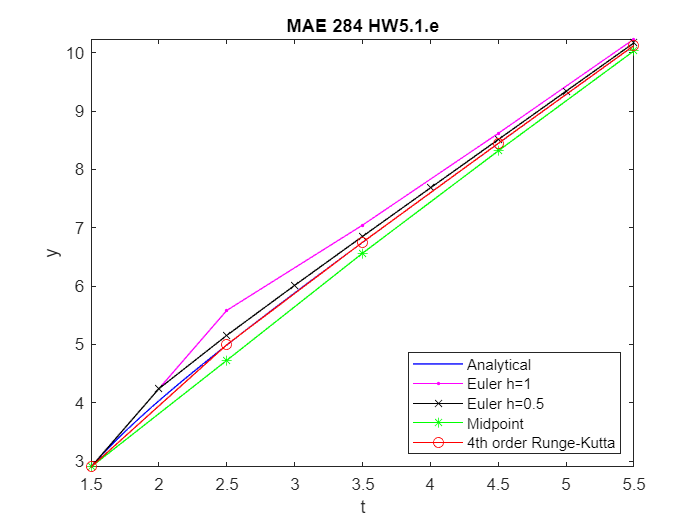

fplot(yExact(x), [x0 xf], "b-")
hold on
plot(x_vals1, y_Euler1, "-m.", x_vals2, y_Euler2, "-kx", x_vals, y_Mid, "-g*", xrk4, yrk4, "-ro")
hold off
xlabel 't'
ylabel 'y'
title 'MAE 284 HW5.1.e'
legend('Analytical', 'Euler h=1', 'Euler h=0.5', 'Midpoint', '4th order Runge-Kutta', 'location','southeast')

## Problem #2 - 4th order Runge-Kutta

**SETUP FOR PROBLEM**

dxdt = @(t,x) 4.3*x - 0.9*exp(-.2*t) - 0.4*t*x;
t0 = 3.8;
tf = 6.3;
x0 = 1.7;
h = 0.5;
t_vals = t0:h:tf;

rk4 = zeros(size(t_vals));
rk4(1) = x0;
for i = 1:(length(rk4)-1)
    k1(i) = dxdt(t_vals(i), rk4(i));
    k2(i) = dxdt(t_vals(i)+h/2, rk4(i)+1/2*k1(i)*h);
    k3(i) = dxdt(t_vals(i)+h/2, rk4(i)+1/2*k2(i)*h);
    k4(i) = dxdt(t_vals(i+1), rk4(i)+k3(i)*h);
    phi(i) = 1/6*(k1(i)+2*k2(i)+2*k3(i)+k4(i));
    rk4(i+1) = rk4(i)+phi(i)*h;
    if i == 1
        fprintf(" i    t       k1       k2       k3       k4      phi        x\n" + ...
                "-- ---- -------- -------- -------- -------- -------- --------\n", t_vals(i), rk4(i))
    end
    fprintf("%2g %4.2f %8.4f %8.4f %8.4f %8.4f %8.4f %8.4f\n", i, t_vals(i+1), k1(i), k2(i), k3(i), k4(i) , phi(i), rk4(i+1))
end

 i    t       k1       k2       k3       k4      phi        x
-- ---- -------- -------- -------- -------- -------- --------


 1 4.30   4.3051   7.0400   8.8725  15.4506   8.5968   5.9984
 2 4.80  15.0950  23.8727  29.3148  48.8162  28.3810  20.1889
 3 5.30  47.7050  72.8947  87.2529 138.8056  84.4676  62.4227
 4 5.80 135.7697 200.1429 233.6170 354.5957 226.3142 175.5798
 5 6.30 347.3659 493.0837 561.5710 812.0750 544.7917 447.9757


## Problem #3 - Mass-spring-damper system

**SETUP FOR PROBLEM**

clear, clc
X0 = [4,2];
c = [2.8 14 70];
k = 1;
m = 49;
t0 = 0;
tf = 24;
[t1,x1] = ode45(@massDamper, [t0 tf], X0, [], c(1), m, k);
[t2,x2] = ode45(@massDamper, [t0 tf], X0, [], c(2), m, k);  
[t3,x3] = ode45(@massDamper, [t0 tf], X0, [], c(3), m, k);

**a) Displacement vs. time plot**

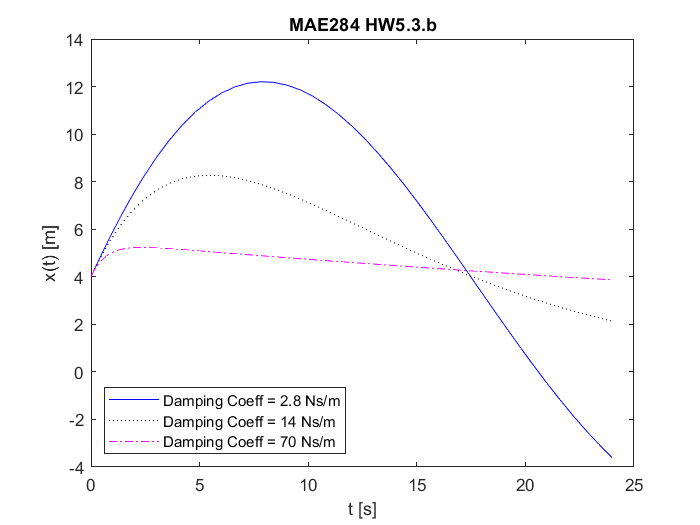

figure()
plot(t1, x1(:,1), "-b", t2, x2(:,1), "k:", t3, x3(:,1), "m-.")
xlabel("t [s]")
ylabel("x(t) [m]")
title("MAE284 HW5.3.b")
legend("Damping Coeff = 2.8 Ns/m", "Damping Coeff = 14 Ns/m","Damping Coeff = 70 Ns/m", "location", "southwest")

**b) Velocity vs. time plot**

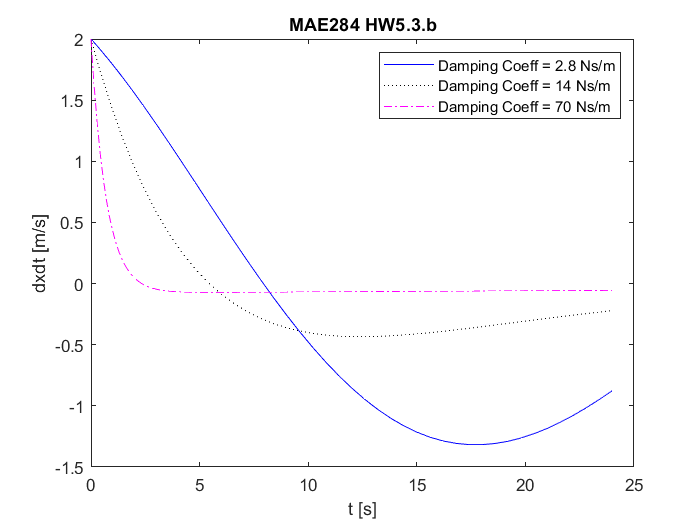

figure()
plot(t1, x1(:,2), "-b", t2, x2(:,2), "k:", t3, x3(:,2), "m-.")
xlabel("t [s]")
ylabel("dxdt [m/s]")
title("MAE284 HW5.3.b")
legend("Damping Coeff = 2.8 Ns/m", "Damping Coeff = 14 Ns/m","Damping Coeff = 70 Ns/m", "location", "northeast")

## Problem #4 - Euler-Cauchy

**SETUP FOR PROBLEM**

y0 = 8;
dy0 =-7;
x0 = 8;
xf = 8.8;
Y0 = [y0 dy0]';

**a) Analytically**

syms y(x)
Dy = diff(y);
ode = diff(y, x, 2)*x^2 + diff(y,x)*8*x + 12*y;
cond1 = y(x0) == 8;
cond2 = Dy(x0) == -7;
conds = [cond1 cond2];

solution(x) = dsolve(ode, conds)

$$solution(x) = -\frac{4096\,\left(3\,x-32\right)}{x^{4}}$$

**b) Implicit Euler's**

$\frac{d^2 y}{{\textrm{dx}}^2 }=\frac{\left(-8x\;\frac{\textrm{dy}}{\textrm{dx}}-12y\right)}{x^2 }$ = $-\frac{8}{x}\frac{\textrm{dy}}{\textrm{dt}}-\frac{12}{x^2 }y$ 

dx = .2;
x = x0:dx:xf;
Y = Y0;

for i = 1:(length(x)-1)
    A = [0 1
        -12/x(i)^2 -8/x(i)];
    M = inv(eye(2) - A*dx);
    Y(:,i+1) = M*Y(:,i);
end
Y = Y'

Y =     8.0000   -7.0000
    6.7909   -6.0455
    5.7449   -5.2301
    4.8386   -4.5315
    4.0523   -3.9316


**c) ode23s**

dY = @(x,Y) [Y(2)
     -12/x^2*Y(1)-8/x*Y(2)]

dY = function_handle with value:
    @(x,Y)[Y(2);-12/x^2*Y(1)-8/x*Y(2)]


[x23, y23] = ode23s(dY, [x0 xf], Y0)

x23 =     8.0000
    8.0800
    8.1600
    8.2400
    8.3200
    8.4000
    8.4800
    8.5600
    8.6400
    8.7200


y23 =     8.0000   -7.0000
    7.4571   -6.5746
    6.9471   -6.1770
    6.4679   -5.8052
    6.0175   -5.4574
    5.5940   -5.1319
    5.1957   -4.8271
    4.8210   -4.5415
    4.4685   -4.2738
    4.1367   -4.0228


**d) Plot of solutions**

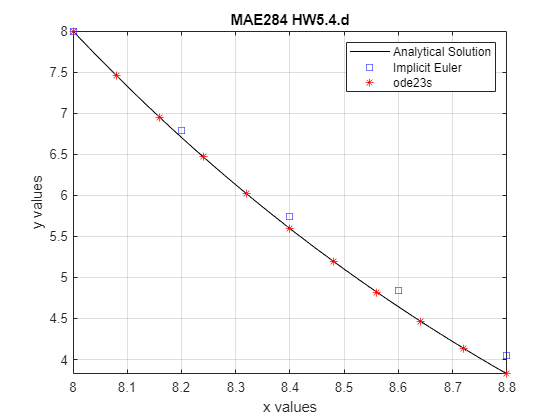

figure()
fplot(solution, [x0,xf], "-k")
hold on
grid on
plot(x, Y(:,1), "sb", x23, y23(:,1), "*r")
xlabel("x values")
ylabel("y values")
title("MAE284 HW5.4.d")
legend("Analytical Solution", "Implicit Euler", "ode23s", "location", "northeast")

## Helper functions

### Problem #3 system function

function dX = massDamper(t, X, c, m, k)
dX = [X(2);
      (-c*X(2)-k*X(1))/m];
end